# Descending 1_CCRN_1_cat 

Read reaction network

foldernam = "Evolution - Praful\"

foldernam = "Evolution - Praful\"

filnam = foldernam +  "1_CCRN_1_cat"

filnam = "Evolution - Praful\1_CCRN_1_cat"

model_nam = "1-CCRN-1-cat"

model_nam = "1-CCRN-1-cat"

[num_spec,species,comp_vec,rxn_rate,G] = extract_rxn_net(filnam);

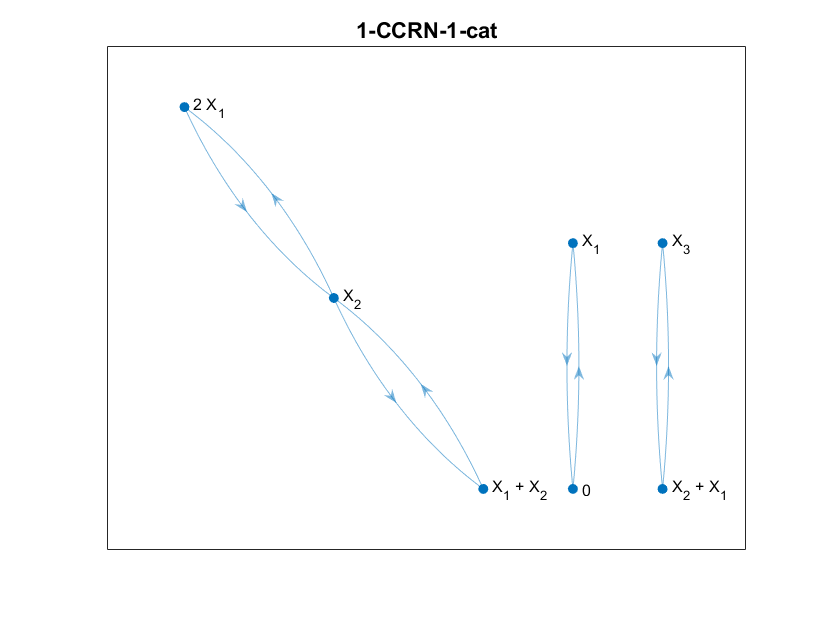

plotter(G,model_nam)
saveas(gcf,foldernam + 'Plots\'+ model_nam + '_hypergraph.png')

%Get Hamiltonian
Ham = get_Hamiltonian(num_spec,comp_vec,rxn_rate)

$$Ham = 0.1476\,{\mathrm{e}}^{p_{1}}+q_{2}\,\left(2.9000\,{\mathrm{e}}^{p_{1}}-2.9000\right)+q_{1}\,\left({\mathrm{e}}^{-p_{1}}-1\right)+q_{2}\,\left(2.0600\,{\mathrm{e}}^{2\,p_{1}-p_{2}}-2.0600\right)+q_{3}\,\left(2.0600\,{\mathrm{e}}^{p_{1}+p_{2}-p_{3}}-2.0600\right)+{q_{1}}^{2}\,\left({\mathrm{e}}^{p_{2}-2\,p_{1}}-1\right)+q_{1}\,q_{2}\,\left({\mathrm{e}}^{p_{3}-p_{2}-p_{1}}-1\right)+q_{1}\,q_{2}\,\left({\mathrm{e}}^{-p_{1}}-1\right)-0.1476$$


%get functions derived from the Hamiltonian needed for the descent
Extract_Hamiltonian

%Get MAK polynomials and the jacobian
[MAK, jac, MAK_fun, jac_fun] = get_MAK(dHamdp,Ham_qp_mix,num_spec);

$$MAK = \left(\begin{array}{c} 7.0200\,q_{2}-q_{1}+2.0600\,q_{3}-2\,q_{1}\,q_{2}-2\,{q_{1}}^{2}+0.1476\\ {q_{1}}^{2}-q_{2}\,q_{1}-2.0600\,q_{2}+2.0600\,q_{3}\\ q_{1}\,q_{2}-2.0600\,q_{3} \end{array}\right)$$


%save Hamiltonian data to file
save(foldernam + 'Data\' + model_nam + '_Ham.mat')


%get roots --- later replace this with Bertini
get_roots_2D

$$pos\_root\_arr = \left(\begin{array}{ccc} 0.7999 & 0.3106 & 0.1206\\ 0.2001 & 0.0194 & 0.0019\\ 1.9000 & 1.7525 & 1.6164 \end{array}\right)$$

x_ic_arr =     0.8007    0.3114    0.1214
    0.7991    0.3098    0.1198


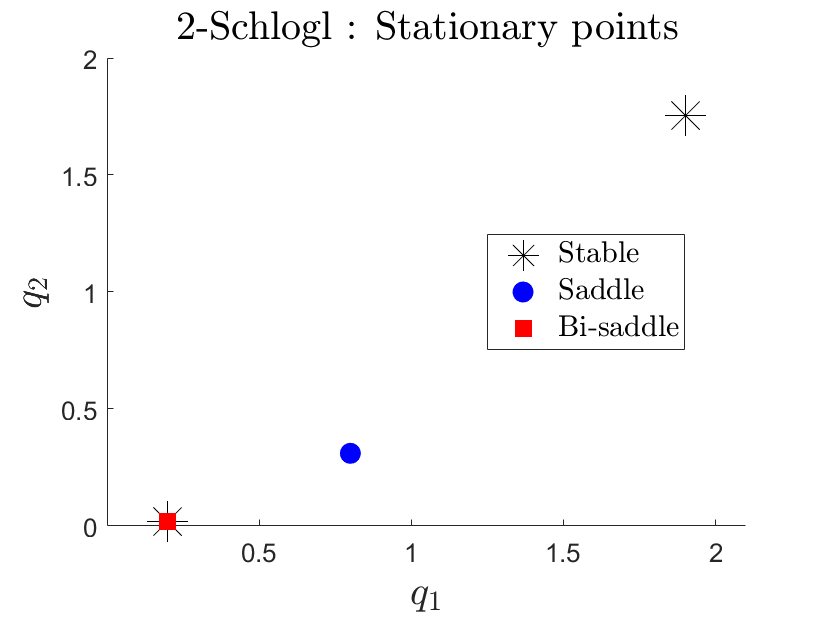

saveas(gcf,foldernam + 'Plots\'+model_nam+'_stability.png')

## Heteroclinic Network

Data saved in

'Examples\Data\' + model_name + '_hcnet.mat'

ans = "Computing time"

Elapsed time is 0.383506 seconds.


ans = "Simulation time"

ans = 360.7900

ans = "Computing time"

Elapsed time is 0.157997 seconds.


ans = "Simulation time"

ans = 147.2000

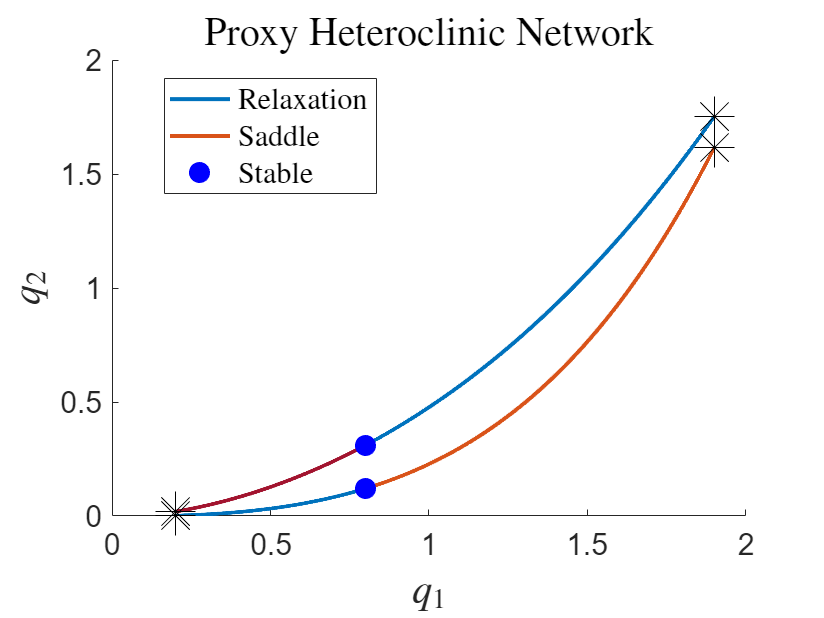

hc_net =      1     3     2


$$pos\_root\_arr = \left(\begin{array}{ccc} 0.7999 & 0.3106 & 0.1206\\ 0.2001 & 0.0194 & 0.0019\\ 1.9000 & 1.7525 & 1.6164 \end{array}\right)$$

Heteroclinic_network

%save hc plot
saveas(gcf,foldernam +'Plots/'+model_nam+'_hcnet.png')


%Save hc_net data
save(foldernam + 'Data\' + model_nam + '_hcnet.mat','pos_root_arr', 'hc_net', 'hc_traj_arr', 'stab_idx', 'sad_idx','t_arr')
